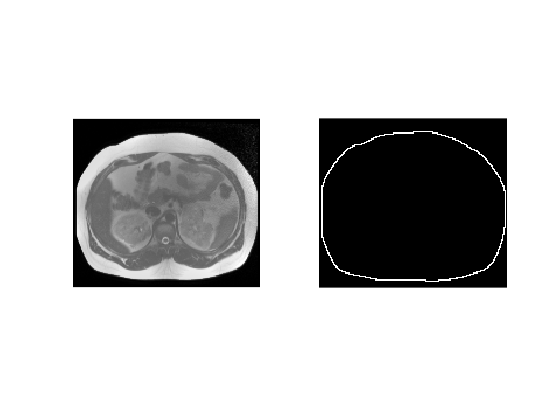

%Load the dataset and show the images with their segmentations
data1 = load("dataForNN_foreBorder_clip0.mat");
data2 = load("dataForNN_foreBorder_clip1.mat");
data3 = load("dataForNN_inside_clip0.mat");

figure();
subplot(1, 2, 1), imshow(data1.trainingImage, []);
subplot(1, 2, 2), imshow(data1.trainingSegmentation, []);

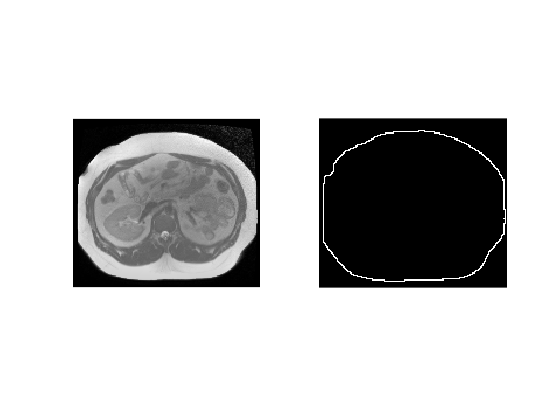


figure();
subplot(1, 2, 1), imshow(data1.testImage, []);
subplot(1, 2, 2), imshow(data1.testSegmentation, []);

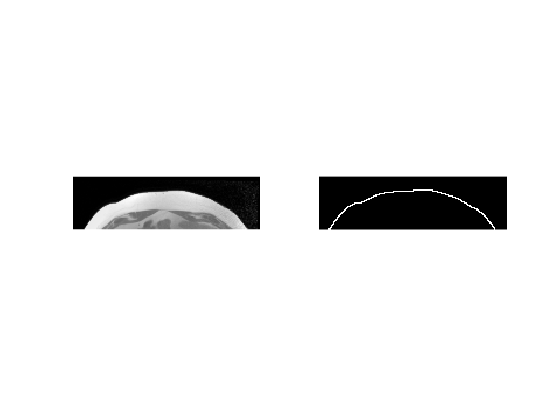



figure();
subplot(1, 2, 1), imshow(data2.trainingImage, []);
subplot(1, 2, 2), imshow(data2.trainingSegmentation, []);

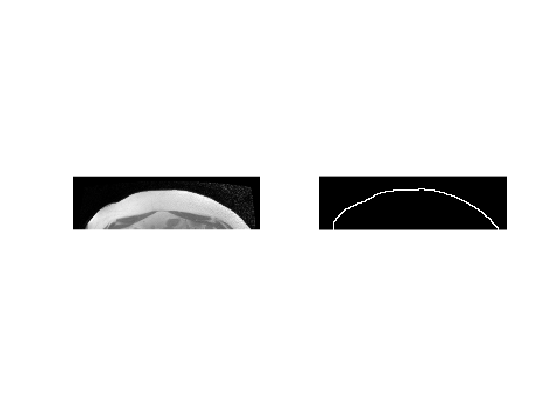


figure();
subplot(1, 2, 1), imshow(data2.testImage, []);
subplot(1, 2, 2), imshow(data2.testSegmentation, []);

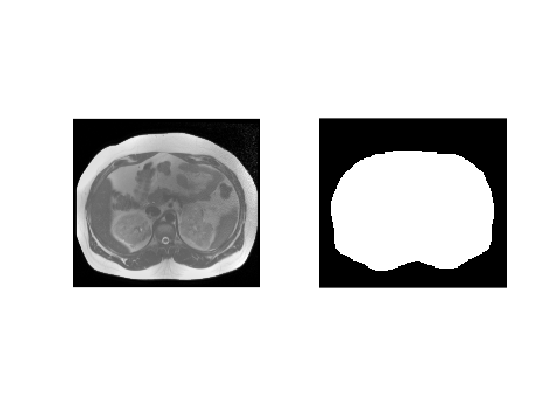


figure();
subplot(1, 2, 1), imshow(data3.trainingImage, []);
subplot(1, 2, 2), imshow(data3.trainingSegmentation, []);

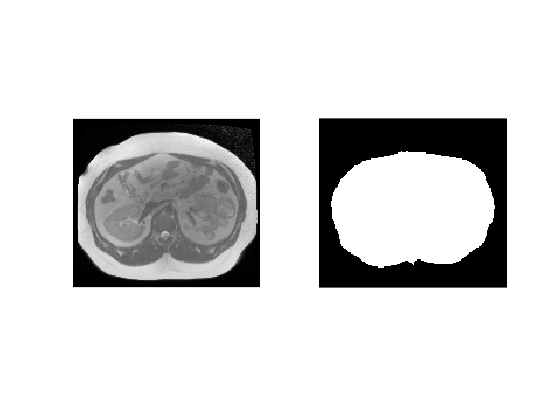


figure();
subplot(1, 2, 1), imshow(data3.testImage, []);
subplot(1, 2, 2), imshow(data3.testSegmentation, []);

%Define Beta vector
Beta = zeros([1, 6]);
ImTrain = data1.trainingImage;
ImSegm = data1.trainingSegmentation;
stepSize = 0.005;

for k = 1:5000
    cost = getCost(Beta, ImTrain, ImSegm, 200);
    delta = 0.001;
    Gradient = zeros(size(Beta));
    if (k < 10)
        disp(cost);
    end
    for i = 1:length(Beta)
        newBeta = Beta;
        newBeta(i) = newBeta(i) + delta;
        newCost = getCost(newBeta, ImTrain, ImSegm, 200);
        Gradient(i) = (newCost - cost) / delta;
    end
    if (k < 10)
        disp(Gradient)
    end
    Beta = Beta - stepSize * Gradient;
end

  138.6294



   94.0250   18.6786  -16.5883   16.6931   42.2341   59.7944



   80.6278



   1.0e+03 *

   -1.0330   -2.1060   -1.3967   -0.9585   -0.2489   -1.3643



   2.3670e+03



   1.0e+05 *

   -1.2276   -5.2828   -1.2122   -3.3966   -2.5793   -3.7998



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



disp(cost);

   NaN



disp(Beta);

   NaN   NaN   NaN   NaN   NaN   NaN



ImTrainRes = zeros(size(ImTrain));
for i = 1:6
    ImTrainRes = ImTrainRes + Beta(i) * BasisFun(ImTrain, i);
end
imshow(ImTrainRes, [])

Error using imageDisplayValidateParams
Expected input number 2, [LOW HIGH], to be non-NaN.

Error in images.internal.checkDisplayRange (line 10)
validateattributes(display_range, {'numeric'},...

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('images.internal.imageDisplayValidateParams', 'C:\Program Files\MATLAB\R2020b\toolbox\matlab\images\+images\+internal\imageDisplayValidateParams.m', 58)" style="font-weight:bold">images.internal.imageDisplayValidateParams<

a = randn([1 50])

a =    -0.0266   -0.7117   -0.3781    0.2189    0.3218   -1.2025   -0.5446   -0.0480   -0.3975    0.2240    0.6568    0.5913    1.1951   -1.3722   -0.3855    0.1947   -0.7155   -1.2537    0.9117    0.2022    0.2449    0.3868    0.7644    0.0015   -1.0108    2.0602    1.3668   -0.4015    0.4596   -1.7945   -1.6705    0.0319    1.5709    0.2668    0.9067    0.5606   -0.1653   -0.9068    1.0497   -1.6883   -0.2585   -0.2873    0.9535    0.0218   -1.1875    0.1085    0.1404   -1.0360    0.7944   -0.6711


randSam = randperm(50, 5)

randSam =     15    34     5    28     8


sort(randSam)

ans =      5     8    15    28    34


a(randSam)

ans =    -0.3855    0.2668    0.3218   -0.4015   -0.0480
